# AOI_Lab : Train Deep OCR 

#### Fred Liu 2023.07.14

在新版本中會漸漸將OCT Trainer的功能轉移到Image Labeler與以下的訓練功能中，

如何進行文字的標記，這部分會再透過後續添加影片來做介紹。

DataSet unzip

datasetZip = 'dseg14.zip';
evalfiles = unzip(datasetZip);

Load Label Date(這邊可以透過Image Labeler來做標記)

但方式稍微會有些不同，之後再作影片補上這一段

ld = load("dseg14Gtruth.mat");
gTruth = ld.gTruth;

labelName：Txet，attributeName：Word

接著透過ocrTrainingData去將資料格式做轉換，將標記資料轉成imds與boxds,txtds資訊

ocrTrainingData是2023a出的新function

labelName = "Text";
attributeName = "Word";
[imds,boxds,txtds] = ocrTrainingData(gTruth,labelName,attributeName);
% 合併
cds = combine(imds,boxds,txtds);

切割資料為訓練與驗證資料，訓練佔九成

% Set the random number seed for reproducibility.
rng(0); 

% Compute number of training and validation samples.
trainingToValidationRatio = 0.9;
numSamples = height(ld.gTruth.LabelData);
numTrainSamples = ceil(trainingToValidationRatio*numSamples);

% Divide the dataset into training and validation.
indices = randperm(numSamples);
trainIndices = indices(1:numTrainSamples);
validationIndices = indices(numTrainSamples+1:end);

cdsTrain = subset(cds, trainIndices);
cdsValidation = subset(cds, validationIndices);

訓練參數設定，並且設定Checkpoints

outputDir = "OCRModel";
if ~exist(outputDir, "dir")
    mkdir(outputDir);
end

checkpointsDir = "Checkpoints";
if ~exist(checkpointsDir, "dir")
    mkdir(checkpointsDir);
end

ocrOptions = ocrTrainingOptions( ...
    GradientDecayFactor=0.9, ...
    InitialLearnRate=40e-4, ...
    MaxEpochs=5, ...
    VerboseFrequency=160, ...
    CheckpointPath=checkpointsDir, ...
    ValidationData=cdsValidation, ...
    OutputLocation=outputDir);

進行訓練

outputModelName = "fourteenSegment";
baseModel = "english";
outputModel = trainOCR(cdsTrain, outputModelName, baseModel, ocrOptions);

*************************************************************************
Starting OCR training

Model Name: fourteenSegment
Base Model: english

Preparing training data... 100.00 % completed.
Preparing validation data... 100.00 % completed.

Character Set: +,-./0123456789ABCDEFGHIJKLMNOPQRSTUVWXYZ

|======================================================================================================================================|
| Epoch | Iteration | Time Elapsed |           Training Statistics           |          Validation Statistics          | Base Learning |
|       |           |  (hh:mm:ss)  |   RMSE   | Character Error | Word Error |   RMSE   | Character Error | Word Error |     Rate      |
|======================================================================================================================================|
|   1   |     1     |   00:00:12   |   9.51   |     100.00      |   100.00   |   0.00   |      0.00       |    0.00    |    0.0040     |
|   1   |    1

單張影像驗證

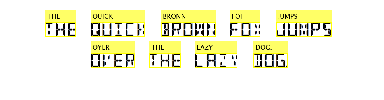

I = imread("DSEG14.png");
ocrResults = ocr(I,Language=outputModel);
Iocr = insertObjectAnnotation(I,"rectangle",...
            ocrResults.WordBoundingBoxes,ocrResults.Words,...
            LineWidth=2,FontSize=17);
figure,imshow(Iocr)

整體資料庫驗證

可以透過evluateOCR來做驗證

originalResult  = ocr(cds, Model=originalModel);
metricsOriginal = evaluateOCR(originalResult, cds);

Evaluating ocr results
----------------------
* Selected metrics: character error rate, word error rate.
* Processed 187 images.
* Finalizing... Done.
* Data set metrics:

    CharacterErrorRate    WordErrorRate
    __________________    _____________

         0.99467                1      



利用QuantizeOCR來做量化加速，比較速度差異

quantizedModel = quantizeOCR(outputModel,"quantizedModel");

fOCR = @() ocr(I, Model=originalModel, LayoutAnalysis="block");
tOCR = timeit(fOCR);

fQuantizedOCR = @() ocr(I, Model=quantizedModel, LayoutAnalysis="block");
tQuantizedOCR = timeit(fQuantizedOCR);

perfRatio = tOCR/tQuantizedOCR;
disp("Quantized model is " + perfRatio + "x faster");

Quantized model is 3.3247x faster


利用`evaluateOCR`來比較原始版本與做量化版本的驗證差異

originalResult  = ocr(cds, Model=originalModel);
quantizedResult = ocr(cds, Model=quantizedModel);

metricsOriginal = evaluateOCR(originalResult, cds);

Evaluating ocr results
----------------------
* Selected metrics: character error rate, word error rate.
* Processed 187 images.
* Finalizing... Done.
* Data set metrics:

    CharacterErrorRate    WordErrorRate
    __________________    _____________

         0.99467                1      



metricsOriginal = evaluateOCR(quantizedResult, cds);

Evaluating ocr results
----------------------
* Selected metrics: character error rate, word error rate.
* Processed 187 images.
* Finalizing... Done.
* Data set metrics:

    CharacterErrorRate    WordErrorRate
    __________________    _____________

         0.29497             0.9893    

